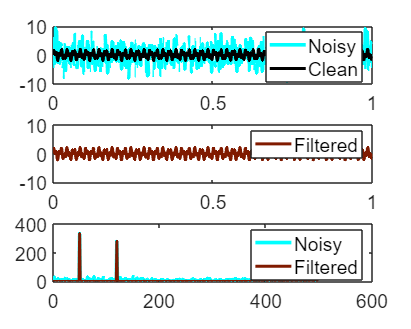

clf;
clear all;

% create a simple signal with 2 frequencies
dt = 0.001;
t = 0:dt:1;
fclean = sin(2*pi*50*t) + sin(2*pi*120*t);
f = fclean + 2.5*randn(size(t)); % add some noise 

figure;
set(gcf,'Position',[1500 200 1000 800]) % Adjust figure size
subplot(3,1,1)
plot(t,f,'c','LineWidth',3), hold on
plot(t,fclean,'k','LineWidth',2.5)
l1 = legend('Noisy','Clean');
set(l1,'FontSize',16) % Adjust legend font size
ylim([-10 10]);
set(gca,'FontSize',16) % Adjust axis font size

% compute fft
n = length(t);
fhat = fft(f,n);  % (data,length of data)
PSD = fhat .* conj(fhat) / n; % power spectrum (power per freq)
freq = 1 / (dt*n) * (0:n); % x-axis of freq in Hz
L = 1:floor(n/2);   % only plot the first half

subplot(3,1,3);
set(gca,'FontSize',12) % Adjust axis font size
plot(freq(L),PSD(L),'c','LineWidth',3)
hold on
set(gca,'FontSize',16) % Adjust axis font size

indices = PSD > 100;
PSDclean = PSD .* indices;
fhat = indices .* fhat;
ffilt = ifft(fhat);

plot(freq(L),PSDclean(L),'-','Color',[0.5 0.1 0],'LineWidth',2.5)
l1 = legend('Noisy','Filtered');
set(l1,'FontSize',16) % Adjust legend font size

subplot(3,1,2);
set(gca,'FontSize',12) % Adjust axis font size
plot(t,ffilt,'-','Color',[0.5 0.1 0],'LineWidth',2.5)
l1 = legend('Filtered');
set(l1,'FontSize',16) % Adjust legend font size
ylim([-10 10]);
set(gca,'FontSize',16) % Adjust axis font size